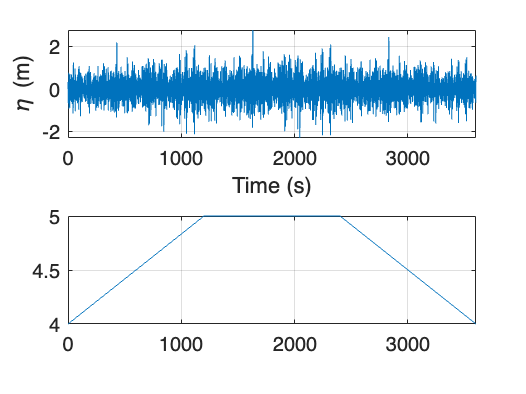

clear;clc;close all;
addpath('functions/')

T1 = 7;  H1 = 1.8;
T2 = 8;  H2 = 2.6;
dur = 1200;  % seconds per segment

% 1st segment: from (H1,T1) → (H2,T2)
[eta1, t1, phi1] = fn_sea_state_transition_mod(H1, T1, H2, T2, dur);

% 2nd segment: hold at (H2,T2) → (H2,T2)
[eta2, t2, phi2] = fn_sea_state_transition_mod(H2, T2, H2, T2, dur, phi1);

% 3rd segment: back (H2,T2) → (H1,T1)
[eta3, t3, phi3] = fn_sea_state_transition_mod(H2, T2, H1, T1, dur, phi2);

% stitch them
t_profile  = [ t1,        t1(end)+t2,         t1(end)+t2(end)+t3 ];
eta_profile= [ eta1,      eta2,               eta3 ];

sea_state = [ 4 + 1/t1(end)*t1, ...
              5*ones(size(t2)), ...
              5 - 1/t3(end)*t3 ];


% plot
figure;
subplot(2,1,1)
plot(t_profile, eta_profile);
xlabel('Time (s)');
ylabel('\eta (m)');
xlim([0, sum(dur)*3]);
grid on;
subplot(2,1,2)
plot(t_profile,sea_state)
grid on;
xlim([0, sum(dur)*3]);

dt = t_profile(2)-t_profile(1);
history_window = round(10*(T2)/2/dt,1);
median_window = round(0.055*history_window)

median_window = 22

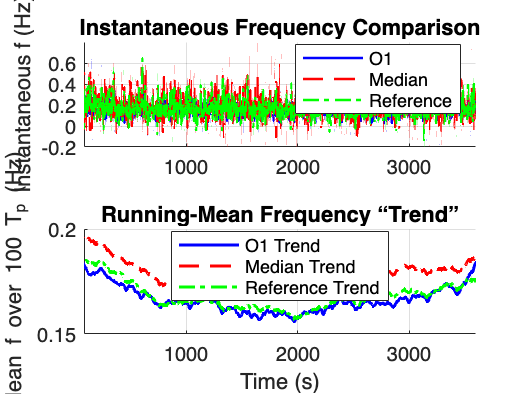

f_t_median = median_inst_f(t_profile',eta_profile',history_window,median_window);

% Compute instantaneous frequency estimates using polynomial orders 0 to 5
f_t_cheat = cheat_inst_f(t_profile',eta_profile', history_window);
f_t_o0 = poly_inst_f(t_profile',eta_profile', history_window, 0);
f_t_o1 = poly_inst_f(t_profile',eta_profile', history_window, 1);
% f_t_o2 = poly_inst_f(t', eta_8to10', history_window, 2);

% === PARAMETERS ===
Tp    = 8;                          % dominant period (s), adjust as needed
dt    = t_profile(2) - t_profile(1);% sample interval
N     = 100;                         % number of periods for smoothing window
M     = round(N * Tp / dt);        % window length in samples

% compute moving‐average trends
f1_trend = movmedian(f_t_o1.inst_freq,         M);
f2_trend = movmedian(f_t_median.inst_freq,     M);
f3_trend = movmedian(f_t_cheat.inst_freq_filtered, M);

% assume t_trim = t_profile is set above
xlims = [Tp*10, t_profile(end)];  % desired x-limits

figure('Name','Frequency Comparison & Trends','NumberTitle','off');

% --- Top: raw instantaneous frequency ---
subplot(2,1,1);
hold on;
  plot(t_profile, f_t_o1.inst_freq,        'b-',  'LineWidth',1.2);
  plot(t_profile, f_t_median.inst_freq,    'r--', 'LineWidth',1.2);
  plot(t_profile, f_t_cheat.inst_freq_filtered, 'g-.', 'LineWidth',1.2);
hold off;
grid on;
ylabel('Instantaneous f (Hz)');
title('Instantaneous Frequency Comparison');
legend({'O1','Median','Reference'}, 'Location','best');
xlim(xlims);            % apply your custom limits
% remove axis tight here!

% --- Bottom: smoothed “trend” curves ---
subplot(2,1,2);
hold on;
  plot(t_profile, f1_trend, 'b-',  'LineWidth',1.5);
  plot(t_profile, f2_trend, 'r--', 'LineWidth',1.5);
  plot(t_profile, f3_trend, 'g-.', 'LineWidth',1.5);
hold off;
grid on;
xlabel('Time (s)');
ylabel(['Mean f over ' num2str(N) ' T_p (Hz)']);
title('Running-Mean Frequency “Trend”');
legend({'O1 Trend','Median Trend','Reference Trend'}, 'Location','best');
xlim(xlims);            % apply the same limits

% now if you really want to tighten *only* the Y-axis you can:
ylim(subplot(2,1,1), ylim(subplot(2,1,1)));  % essentially a no-op on X
ylim(subplot(2,1,2), ylim(subplot(2,1,2)));

% % Create a tiled layout with 6 rows and 1 column
% tlo = tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
% 
% % Define the time range and frequency limits for all plots
% time_range = [100, 2400];
% freq_limits = [0, 0.3];
% 
% % Define a cell array of polynomial orders and their corresponding data
% poly_orders = {0, f_t_o0; 1, f_t_o1; 2, f_t_o2;};
% titles = {'Polynomial Order 0', 'Polynomial Order 1', 'Polynomial Order 2', 'Median Filter'};
% 
% % Loop through each polynomial order and create a plot
% for i = 1:length(poly_orders)
%     % Create an axes object in the tiled layout
%     ax = nexttile;
% 
%     % Plot the estimated instantaneous frequency for the current polynomial order
%     plot(t, poly_orders{i, 2}.inst_freq, 'b-', 'LineWidth', 1.5); hold on;
% 
%     % Plot the 'cheat' method's instantaneous frequency
%     plot(t, f_t_cheat.inst_freq_filtered, 'r--', 'LineWidth', 1.5);
% 
%     % Set plot limits
%     xlim(time_range);
%     ylim(freq_limits);
% 
%     % Add labels and title
%     ylabel('Frequency (Hz)');
%     title(titles{i});
% 
%     % Add legend
%     legend(['Order ', num2str(poly_orders{i, 1})], 'Cheat Method', 'Location', 'best');
% 
%     % Add grid for better readability
%     grid on;
% end
% 
% % Add the median filter result in the last subplot
% ax = nexttile;
% plot(t, f_t_median.inst_freq, 'b-', 'LineWidth', 1.5); hold on;
% plot(t, f_t_cheat.inst_freq_filtered, 'r--', 'LineWidth', 1.5);
% xlim(time_range);
% ylim(freq_limits);
% ylabel('Frequency (Hz)');
% title('Median Filter');
% legend('Median Filter', 'Cheat Method', 'Location', 'best');
% grid on;
% 
% % Add a common xlabel at the bottom of the figure
% xlabel(tlo, 'Time (s)');
% 